# **ACTIVIDAD 1.9 (Landmarks)**

**Jesús Alejandro Gómez Bautista | A01736171**

**PARTE I. Seguimiento de waypoints**

Para implementar el seguimiento de los waypoints en esta primera parte de la actividad, me concentré en identificar todos los landmarks existentes en el plano y definirlos en orden alfabético en el vector de waypoints de cada código. Las primeras coordenadas en este vector serían las mismas que las del punto inicial.

Tanto la velocidad angular como la velocidad lineal en estos modelos se mantuvieron en los valores proporcionados por el ejemplo visto en clase, al igual que la distancia de visión del robot.

Una modificación eurística en el código se relaciona con el tiempo de ejecución del programa. Se ajustó tanto el tamaño del intervalo de muestreo como el vector de tiempo para que muchos de los ejercicios no terminen inmediatamente cuando el robot llega al punto, sino en el momento en que se completa la ruta en función del tiempo de muestreo aproximado.

Respecto a la manera en que el robot cambia de dirección, en estos ejemplos se observa que, debido a los cambios bruscos de dirección y al mantener constantes tanto la velocidad angular como la lineal, el robot realiza rotaciones amplias hasta posicionarse en línea recta hacia el siguiente punto. Esto contrasta con los trazos "rectos" entre cambios que se han observado en simulaciones anteriores. La estrategia actual favorece la precisión en la ruta, sacrificando la suavidad de los movimientos.

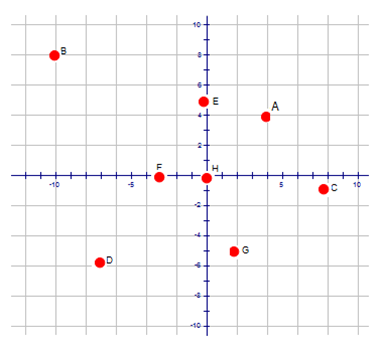

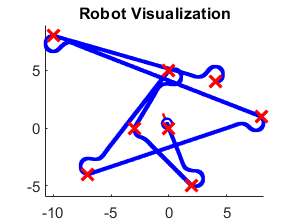

%%%%%% EJERCICIO I %%%%%%
%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:91;         % Time array

initPose = [4;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,4; -10,8; 8,1; -7,-4; 0,5; -3,0; 2,-5; 0,0];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

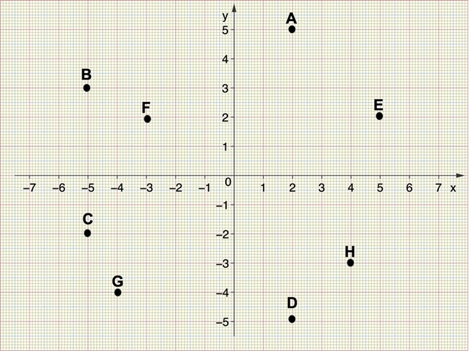

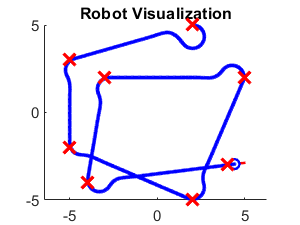

%%%%%% EJERCICIO II %%%%%%
%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:54;         % Time array

initPose = [2;5;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [2,5; -5,3; -5,-2; 2,-5; 5,2; -3,2; -4,-4; 4,-3];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

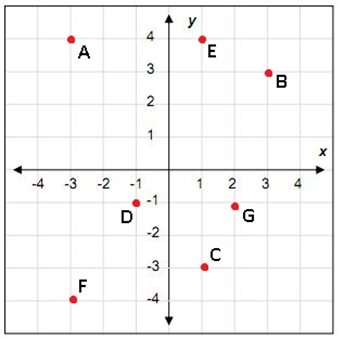

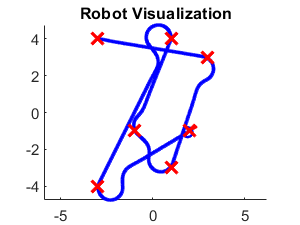

%%%%%% EJERCICIO III %%%%%%
%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:40;         % Time array

initPose = [-3;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [-3,4; 3,3; 1,-3; -1,-1; 1,4; -3,-4; 2,-1];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

**PARTE II. Generar los waypoints**

En contraste con la actividad anterior, en esta parte tuvimos la responsabilidad de especificar las landmarks en el plano, ajustándolas a las necesidades del programa. Aunque la opción de utilizar el menor número de waypoints era viable, opté por una estrategia precisa, evitando la creación de trazos innecesarios a menos que fueran estrictamente necesarios, como en el caso de figuras interiores.

A diferencia del ejercicio anterior, en este caso no solo ajustamos el tiempo de muestreo de manera heurística y los waypoints, que fueron considerablemente más numerosos que antes, sino que también modificamos elementos como la velocidad angular y lineal. Incrementamos la velocidad angular para reducir las rotaciones prolongadas observadas en los ejercicios anteriores, minimizándolas tanto como fuera posible. La velocidad angular se mantuvo baja para evitar giros excesivos y hacer más fácil para el robot la rotación.

Además, redujimos la distancia del robot para evitar rotaciones prematuras debido a los ajustes realizados anteriormente, lo que a menudo resultaba en el robot no pasando por los puntos establecidos.

Estimar los tiempos de ejecución no fue una tarea sencilla. Realizamos ejecuciones con tiempos tanto por encima como por debajo del valor esperado, muchas veces ajustando hacia abajo hasta llegar al resultado más aproximado. Este proceso implicó iteraciones y pruebas repetidas para lograr un equilibrio entre precisión y eficiencia en la ruta del robot.

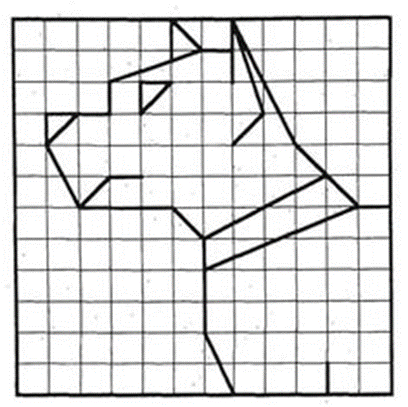

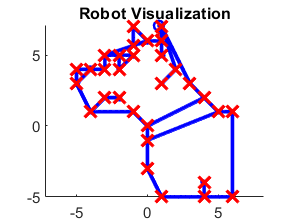

%%%%%% EJERCICIO PERRO %%%%%%
%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:161;         % Time array

initPose = [1;3;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [1,3; 2,4; 1,7; 1,6; 1,5; 1,6; 0,6; -1,7; -1, 5.7; 0,6; -3,5; -2,5; -1,5; -2,4; -2,5; 
            -3,5; -3,4; -5,4; -5,3; -4,4; -5,3; -4,1; -3,2; -2,2; -3,2; -4,1; -1,1; 0,0; 4,2; 5,1;
            0,-1; 0,0; 0,-3; 1,-5; 4,-5; 4,-4; 4,-5; 6,-5; 6,1; 5,1; 3,3; 1,7];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.1;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 7;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

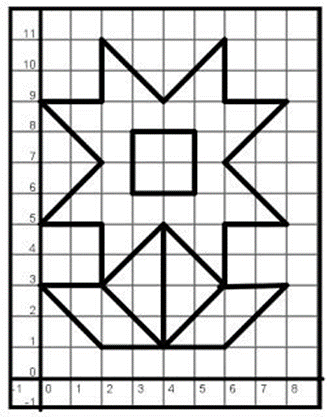

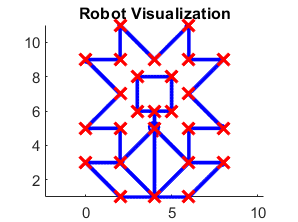

%%%%%% EJERCICIO FLOR %%%%%%
%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:145;         % Time array

initPose = [4;1;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,1; 4,5; 4,6; 5,6; 5,8; 3,8; 3,6; 4,6; 4,5; 6,3; 8,3; 6,1; 2,1; 0,3; 2,3; 4,1; 6,3;
             6,5; 8,5; 6,7; 8,9; 6,9; 6,11; 4,9; 2,11; 2,9; 0,9; 2,7; 0,5; 2,5; 2,3; 4,5];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.1;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 7;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

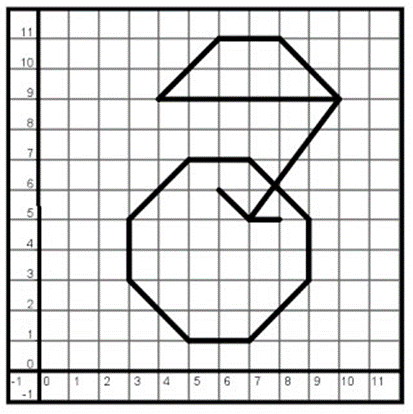

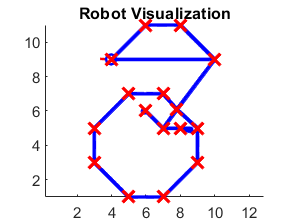

%%%%%% EJERCICIO CEREZA / MANZANA %%%%%%
%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:83;         % Time array

initPose = [4;9;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,9; 6,11; 8,11; 10,9; 7,5; 8,5; 7,5; 6,6; 7,5; 7.8,6.1; 
             7,7; 5,7; 3,5; 3,3; 5,1; 7,1; 9,3; 9,5; 7.8,6.1; 10,9; 4,9];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.1;
controller.DesiredLinearVelocity = 0.6;
controller.MaxAngularVelocity = 7;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end